# DIP Assignment 4

## Question 1

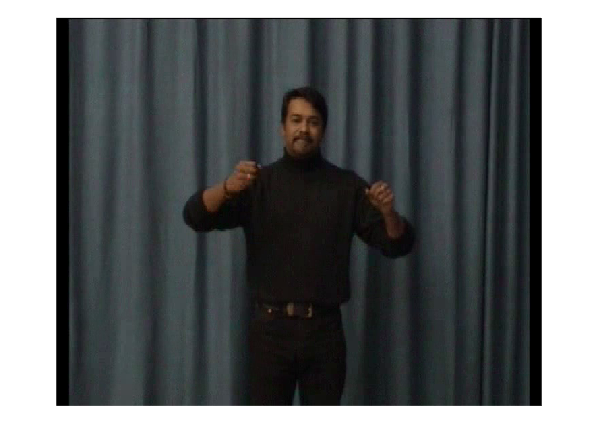

clear
clc
s1 = imread("input\signer_1.bmp");
s2 = imread("input\signer_2.bmp");
s3 = imread("input\signer_3.bmp");
imshow(s2)

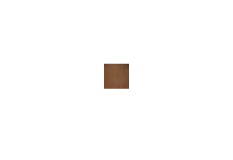

% 453:473,344:369 top of hand
% 128:144,346:365 forehead
subimage_hand = s1(454:473,350:369,:);
subimage_forehead = s1(125:144,346:365,:);
subimage = 0.5*(subimage_hand+subimage_forehead);
% subimage = subimage_hand;
imshow(subimage)

sigma_red = std2(subimage(:,:,1));
sigma_green = std2(subimage(:,:,2));
sigma_blue = std2(subimage(:,:,3));
mu_red = mean2(subimage(:,:,1));
mu_green = mean2(subimage(:,:,2));
mu_blue = mean2(subimage(:,:,3));
sigmas = [sigma_red;sigma_green;sigma_blue];
mus = [mu_red;mu_green;mu_blue];
disp(table({'Red';'Green';'Blue'},mus,sigmas,'VariableNames',{'Colour','Avg','StdDev'}))

     Colour       Avg      StdDev
    _________    ______    ______
    {'Red'  }    121.79    8.0779
    {'Green'}    80.975     7.087
    {'Blue' }    55.072     5.717


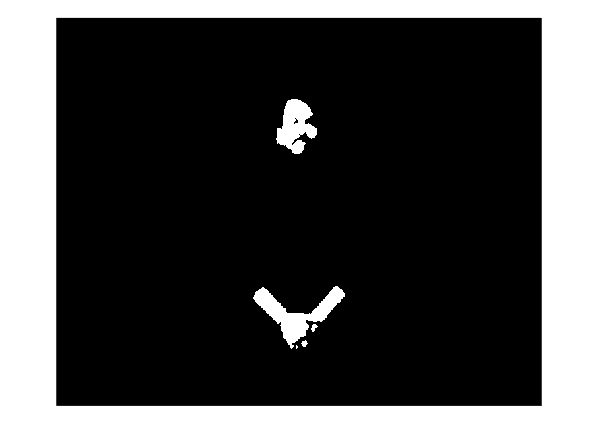

cube_size = 4.9;
lower_bound = [mu_red - cube_size*sigma_red, mu_green - cube_size*sigma_green, mu_blue - cube_size*sigma_blue];
upper_bound = [mu_red + cube_size*sigma_red, mu_green + cube_size*sigma_green, mu_blue + cube_size*sigma_blue];

s1_mask = segment_skin(s1, lower_bound, upper_bound);
s2_mask = segment_skin(s2, lower_bound, upper_bound);
s3_mask = segment_skin(s3, lower_bound, upper_bound);

imshow(imdilate(s1_mask,strel('disk',2)))

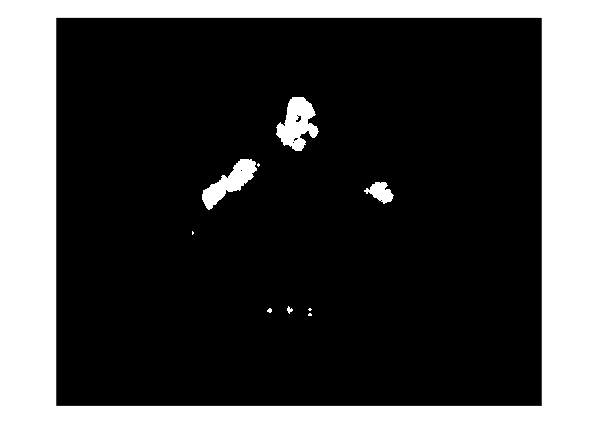

imshow(imdilate(s2_mask,strel('disk',2)))

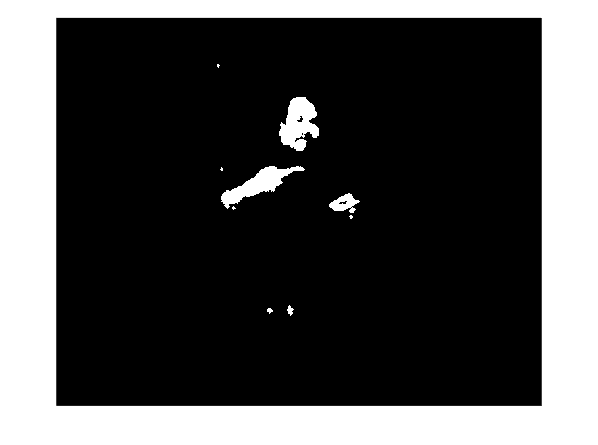

imshow(imdilate(s3_mask,strel('disk',2)))

b) We need to handle s1 and s2,s3 seperately:

Let's first do s1.

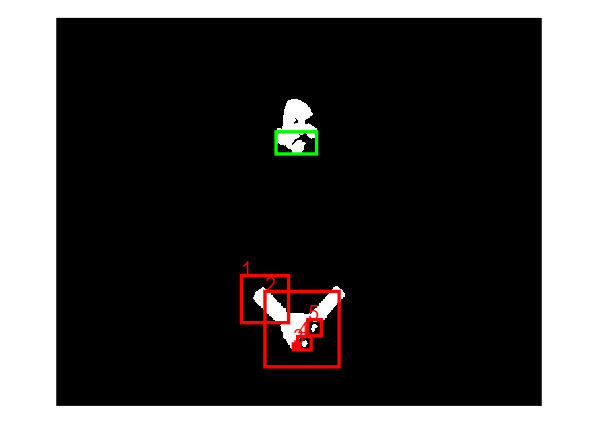

% Assuming 'img' is your binary image with skin pixels segmented
img = imdilate(s1_mask, strel('disk', 2));

% Step 1: Find connected components
[labeled, ~] = bwlabel(img);
stats = regionprops(labeled, 'Area', 'BoundingBox', 'PixelIdxList');

% Sort components by area in descending order
[~, sortIdx] = sort([stats.Area], 'descend');
stats = stats(sortIdx);

% The face is the second largest component
faceIdx = 2;

% Create face mask
face_mask = false(size(img));
face_mask(stats(faceIdx).PixelIdxList) = true;

% Remove face from the image
img_no_face = img & ~face_mask;

% Steps 2-5 remain the same as before
se = strel('disk', 12);
img_closed = imclose(img_no_face, se);
img_opened = imopen(img_closed, se);
skeleton = bwskel(img_opened);
endpoints = bwmorph(skeleton, 'endpoints');
se_hand = strel('disk', 20);
hand_regions = imdilate(endpoints, se_hand) & img_no_face;

% Get properties of hand regions
hand_stats = regionprops(hand_regions, 'Area', 'BoundingBox');

% Increase bounding box size
expansion_factor = 2; % Increase size by 20%
for i = 1:length(hand_stats)
    bb = hand_stats(i).BoundingBox;
    center = [bb(1) + bb(3)/2, bb(2) + bb(4)/2];
    new_width = bb(3) * expansion_factor;
    new_height = bb(4) * expansion_factor;
    hand_stats(i).BoundingBox = [center(1) - new_width/2, center(2) - new_height/2, new_width, new_height];
end

% Visualize results and allow manual selection
figure;
imshow(img);
hold on;

% Draw bounding boxes for all hand regions
for i = 1:length(hand_stats)
    bb = hand_stats(i).BoundingBox;
    h = rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
    text(bb(1), bb(2)-10, num2str(i), 'Color', 'r', 'FontSize', 12);
end

% Draw bounding box for bottom 40% of face region
face_bb = stats(faceIdx).BoundingBox;
mouth_bb = face_bb;
mouth_bb(2) = mouth_bb(2) + mouth_bb(4) * 0.6;  % Start at 60% from top
mouth_bb(4) = mouth_bb(4) * 0.4;  % 40% of original height
rectangle('Position', mouth_bb, 'EdgeColor', 'g', 'LineWidth', 2);

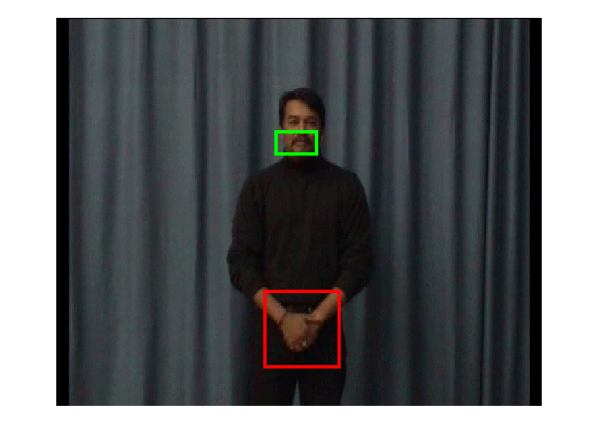


% Manual selection
selected_indices = input('Enter the number(s) of the hand region(s) you want to keep (e.g., 1 or [1 3]): ');
if ~isempty(selected_indices)
    selected_indices = selected_indices(1:min(2, length(selected_indices))); % Ensure at most two are selected
end

% Clear the figure and redraw only selected hand regions
clf;
imshow(s1);
hold on;

for i = 1:length(selected_indices)
    bb = hand_stats(selected_indices(i)).BoundingBox;
    rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
end

% Redraw mouth region
rectangle('Position', mouth_bb, 'EdgeColor', 'g', 'LineWidth', 2);
hold off

Now we do s2 and s3

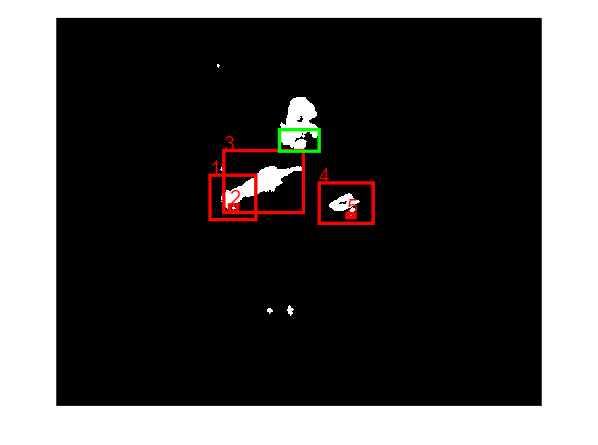

% Assuming 'img' is your binary image with skin pixels segmented
img = imdilate(s3_mask, strel('disk', 2));

% Step 1: Find and remove the face region
[labeled, ~] = bwlabel(img);
stats = regionprops(labeled, 'Area', 'BoundingBox', 'PixelIdxList');
[~, idx] = max([stats.Area]);
face_mask = false(size(img));
face_mask(stats(idx).PixelIdxList) = true;

% Remove face from the image
img_no_face = img & ~face_mask;

% Step 2: Find potential arm-like structures
se = strel('disk', 12);
img_closed = imclose(img_no_face, se);
img_opened = imopen(img_closed, se);

% Step 3: Skeletonize to find arm structures
skeleton = bwskel(img_opened);

% Step 4: Find endpoints of the skeleton (potential hand locations)
endpoints = bwmorph(skeleton, 'endpoints');

% Step 5: Dilate endpoints to get hand regions
se_hand = strel('disk', 20);
hand_regions = imdilate(endpoints, se_hand) & img_no_face;

% Get properties of hand regions
hand_stats = regionprops(hand_regions, 'Area', 'BoundingBox');

% Increase bounding box size
expansion_factor = 2; % Increase size by 20%
for i = 1:length(hand_stats)
    bb = hand_stats(i).BoundingBox;
    center = [bb(1) + bb(3)/2, bb(2) + bb(4)/2];
    new_width = bb(3) * expansion_factor;
    new_height = bb(4) * expansion_factor;
    hand_stats(i).BoundingBox = [center(1) - new_width/2, center(2) - new_height/2, new_width, new_height];
end

% Visualize results and allow manual selection
figure;
imshow(img);
hold on;

% Draw bounding boxes for all hand regions
for i = 1:length(hand_stats)
    bb = hand_stats(i).BoundingBox;
    h = rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
    text(bb(1), bb(2)-10, num2str(i), 'Color', 'r', 'FontSize', 12);
end

% Draw bounding box for bottom 40% of face region
face_bb = stats(idx).BoundingBox;
mouth_bb = face_bb;
mouth_bb(2) = mouth_bb(2) + mouth_bb(4) * 0.6;  % Start at 60% from top
mouth_bb(4) = mouth_bb(4) * 0.4;  % 40% of original height
rectangle('Position', mouth_bb, 'EdgeColor', 'g', 'LineWidth', 2);

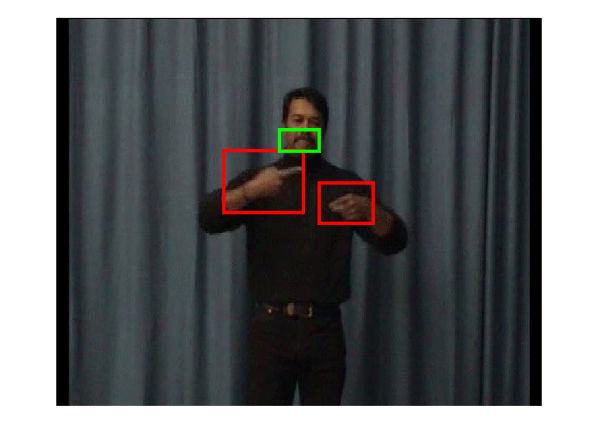

% Manual selection
selected_indices = input('Enter the numbers of the two hand regions you want to keep (e.g., [1 3]): ');
selected_indices = selected_indices(1:min(2, length(selected_indices))); % Ensure only two are selected

% Clear the figure and redraw only selected hand regions
clf;
imshow(s3);
hold on;

for i = 1:length(selected_indices)
    bb = hand_stats(selected_indices(i)).BoundingBox;
    rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
end

% Redraw mouth region
rectangle('Position', mouth_bb, 'EdgeColor', 'g', 'LineWidth', 2);
hold off

## Question 2:

a)

clear

disks = imread('input\disks.tif');
disks = ~imbinarize(disks);

se_all = strel('disk', 1);
all_disks = imopen(disks, se_all);
[~,total] = bwlabel(all_disks);
num_large = 0;

for r = 1:50
    se_large = strel('disk', r);
    large_disks = imopen(disks, se_large);
    [~,n] = bwlabel(large_disks);
    if n ~= 0 && n ~= total
        num_large = n;
    end
end
disp(table([total;total-num_large;num_large],'RowNames',{'Total disks','Small disks','Large disks'},'VariableNames',{'Count'}))

                   Count
                   _____
    Total disks     46  
    Small disks     31  
    Large disks     15  


b)

i)

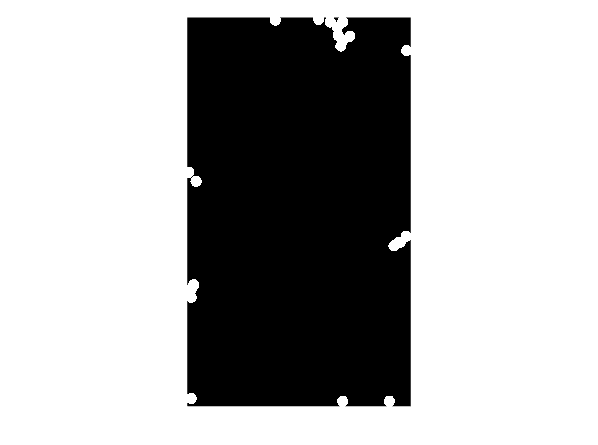

I = imread('input\particles.jpg');
I_bin = imbinarize(I(:,:,1));

border_mask = zeros(size(I_bin));
border_mask(1,:) = 1; border_mask(end,:) = 1;
border_mask(:,1) = 1; border_mask(:,end) = 1;

border_particles = imreconstruct(border_mask & I_bin, I_bin);
imshow(border_particles)

[~,numObjects] = bwlabel(border_particles)

numObjects = 10

ii)

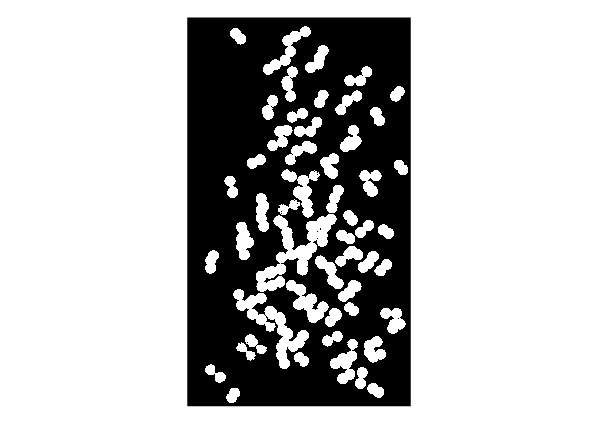

segment = I_bin & ~border_particles;
canvas = zeros(size(segment));
for deg = 0:5:360
    line = strel('line',26,deg);
    connected = imopen(segment,line);
    canvas = canvas | connected;
    imshow(canvas)
    pause(0.1)
end

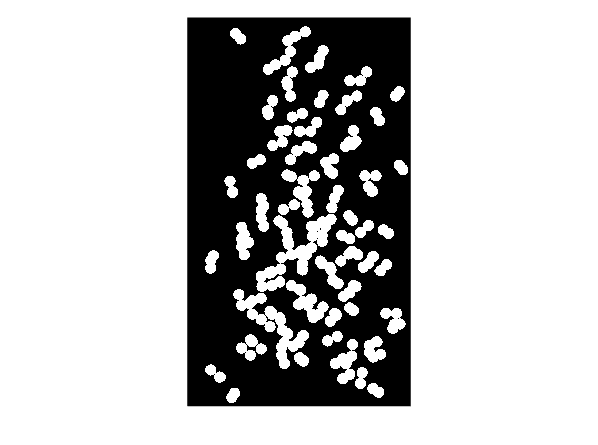

overlapping = imreconstruct(canvas, I_bin);
imshow(overlapping)

[lw, num_components] = bwlabel(overlapping);
num_components

num_components = 55

iii)

non_overlap = segment & ~overlapping;
[~, num_components] = bwlabel(non_overlap);
num_components

num_components = 64

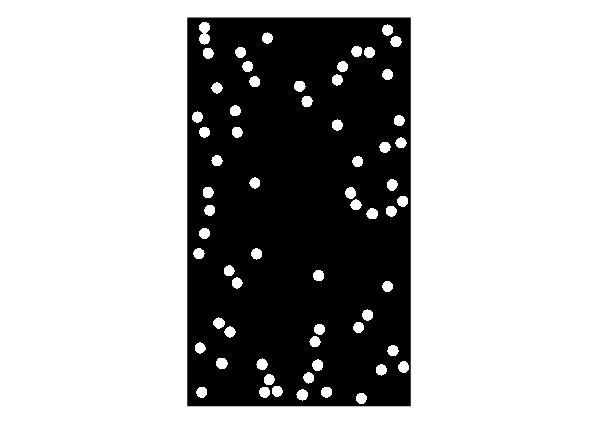

imshow(non_overlap)

c)

Here we must estimate the total amount of particles in the images.

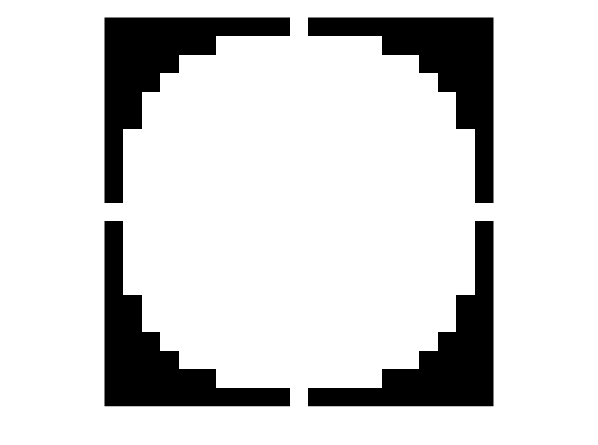

se = strel("disk",10,0);
imshow(se.Neighborhood)

se_area = nnz(se.Neighborhood)

se_area = 317

closed = imopen(segment,se);
closed_area = nnz(closed)

closed_area = 90491

closed_area/se_area

ans = 285.4606

## Question 3

**A**

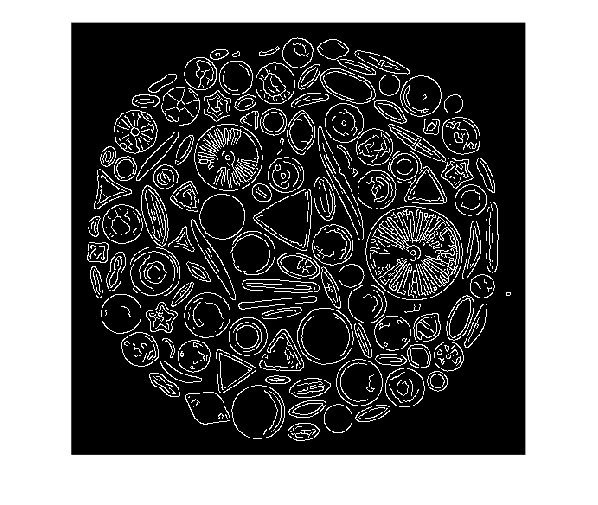

clear
diatoms = imread('input\diatoms.jpg');

% Convert to grayscale if needed
if size(diatoms, 3) == 3
    gray_img = rgb2gray(diatoms);
else
    gray_img = img;
end

% Edge detection
edges = edge(gray_img, 'Canny');
imshow(edges)

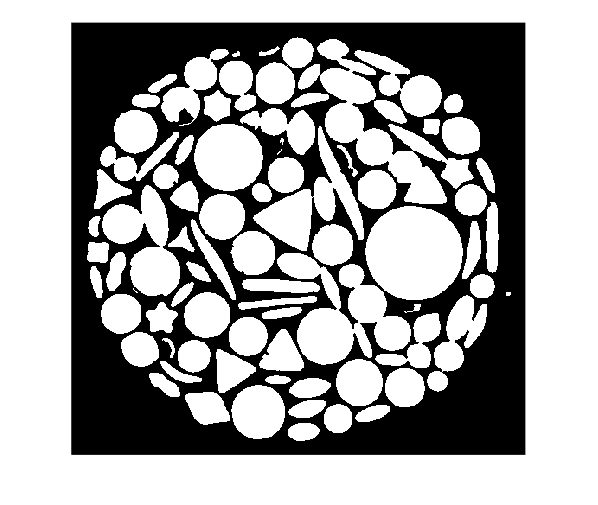

% Fill holes
smoothed_edges = imdilate(edges,strel("sphere",1));
filled_img = imfill(smoothed_edges, 'holes');
filled_img = imerode(filled_img,strel('disk',1));

imshow(filled_img);

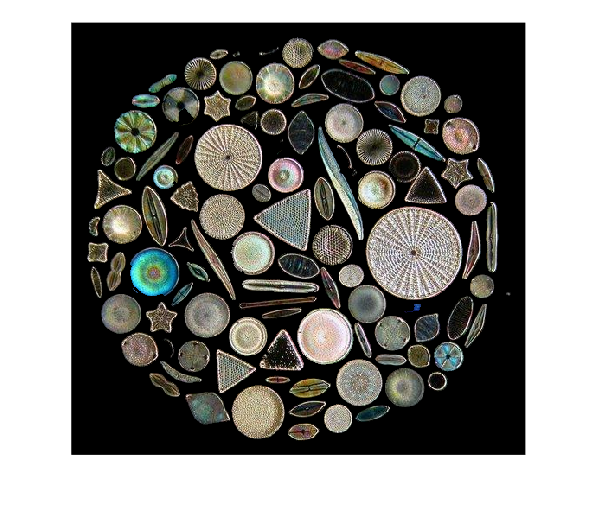

imshow(uint8(filled_img).*diatoms);

**B**

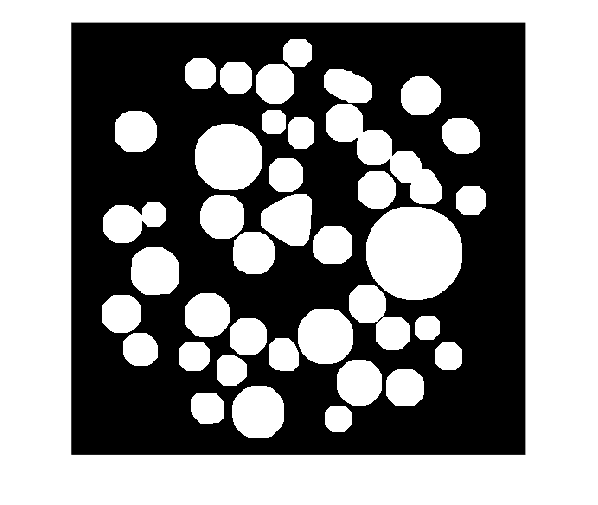

segment = filled_img;
round = strel('disk',14);
round_diatoms = imopen(segment,round);
imshow(round_diatoms)

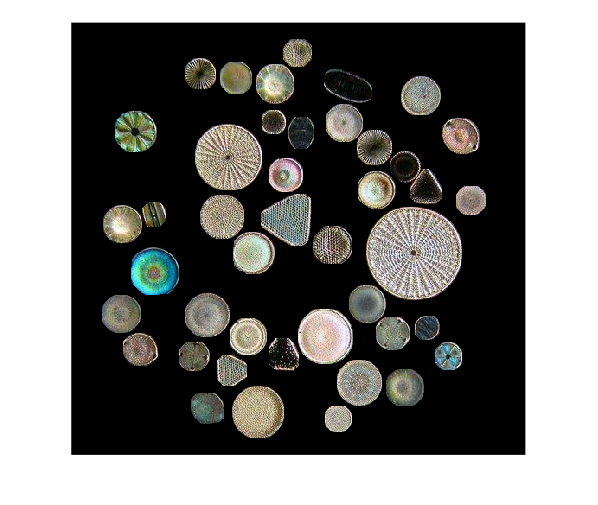

imshow(uint8(round_diatoms).*diatoms);

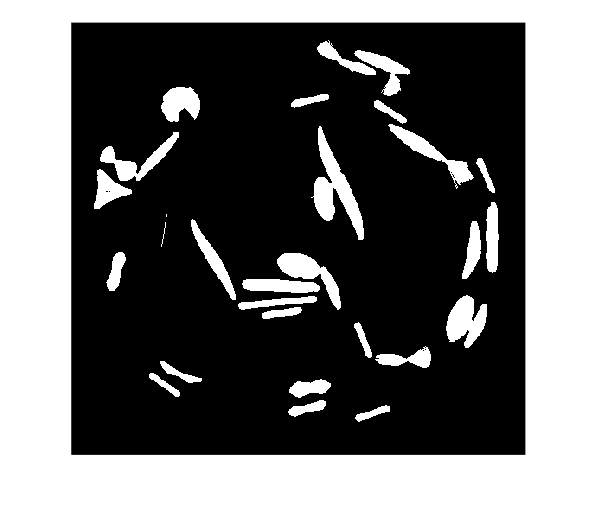

% Now let's try elongated diatoms:
segment = segment & ~round_diatoms;
full_elongated = zeros(size(segment));
for deg = 0:5:360
    line = strel('line',40,deg);
    elongated_diatoms = imopen(segment,line);
    full_elongated = full_elongated | elongated_diatoms;
end
imshow(full_elongated)

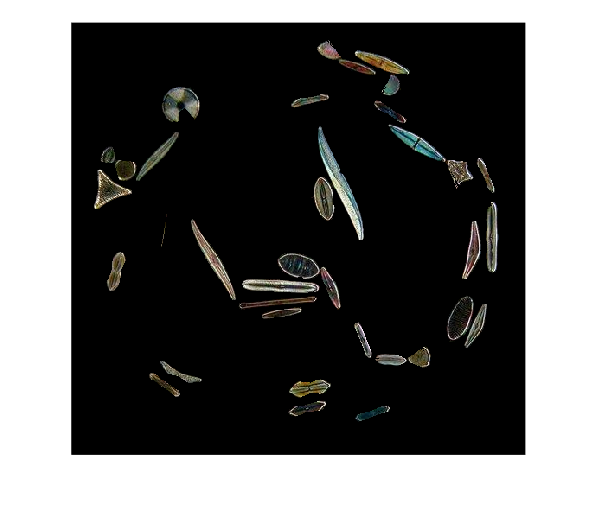

imshow(uint8(full_elongated).*diatoms);

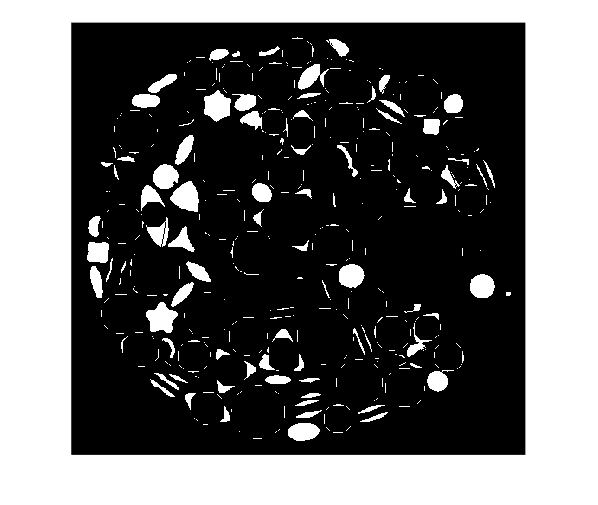

segment = segment & ~full_elongated;
imshow(segment)

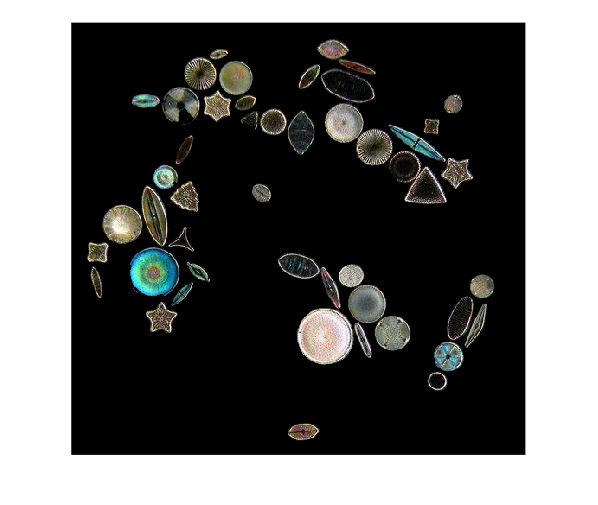

small = strel('disk',6);
border_removed = imopen(segment,small);
misc = imreconstruct(border_removed,filled_img);
imshow(uint8(misc).*diatoms)

## Question 4

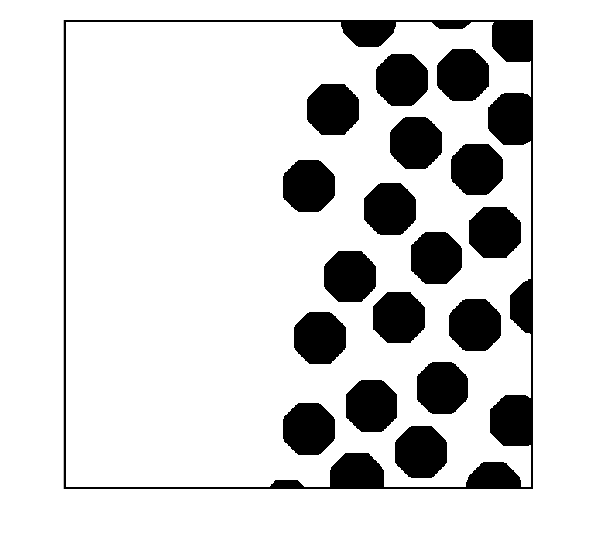

clear
clf
blobs = imread("input\blobs.tif");
close_se = strel('disk',30);
closed = ~imbinarize(imclose(blobs,close_se));
closed(1:end,1:200) = 0;
imshow(padarray(~closed,[3 3]))

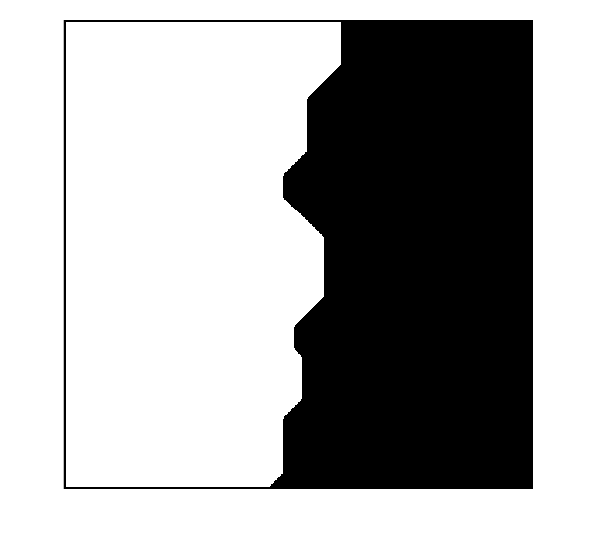

% closed = imclearborder(closed);
open_se = strel('disk',60);
open = imopen(~closed,open_se);
open(1:end,1:200) = 1;
imshow(padarray(open,[3 3]))

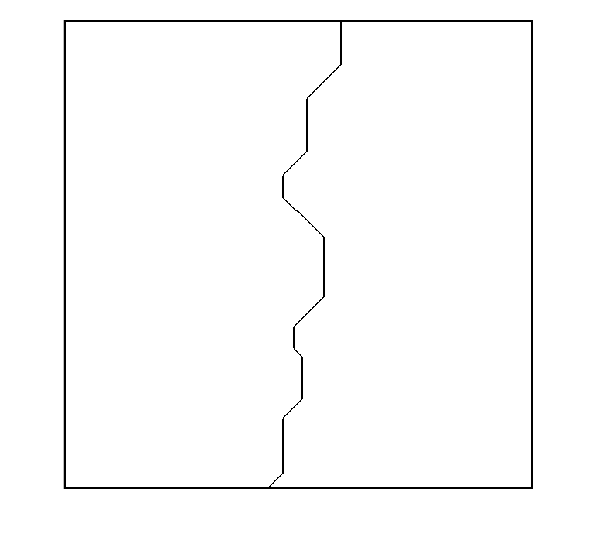

se_gradient = strel('disk', 1);
gradient = imsubtract(imdilate(open, se_gradient), imerode(open, se_gradient));
level = graythresh(gradient);
binary_gradient = ~imbinarize(gradient, level);
imshow(padarray(binary_gradient,[3 3]))

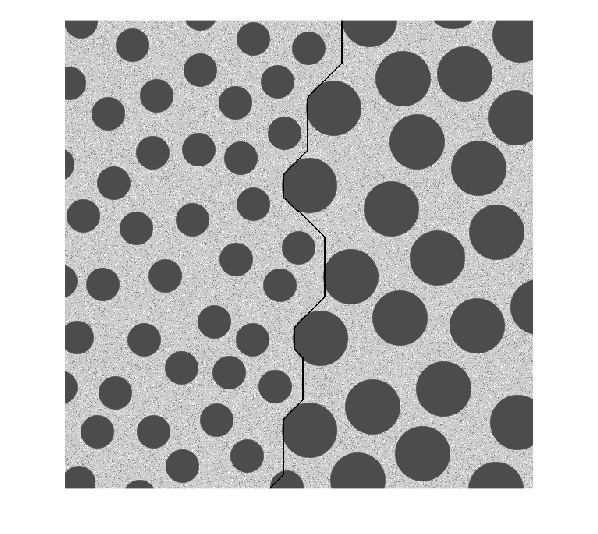

imshow(uint8(binary_gradient).*blobs)

FUNCTIONS

function skin_mask = segment_skin(img, lower_bound, upper_bound)
    skin_mask = (img(:,:,1) >= lower_bound(1) & img(:,:,1) <= upper_bound(1)) & ...
                (img(:,:,2) >= lower_bound(2) & img(:,:,2) <= upper_bound(2)) & ...
                (img(:,:,3) >= lower_bound(3) & img(:,:,3) <= upper_bound(3));
end
